# Q4 (a)

s = tf('s');
G = (s+1)/(s^2+0.2*s+5);
WI = (10*s + 10)/(s+1000);
G_ss = ss(G)

G_ss =
 
  A = 
         x1    x2
   x1  -0.2  -2.5
   x2     2     0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
        x1   x2
   y1    1  0.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



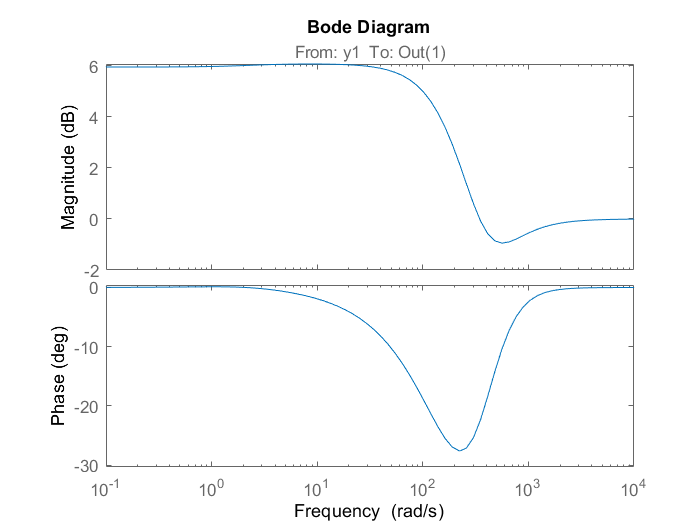

% LQG
QXU = blkdiag(5*1e4*G_ss.C'*G_ss.C,1);
QWV = blkdiag(1e5*eye(2),1);
Klqg = lqg(G_ss,QXU,QWV);

Slqg = 1-feedback(G_ss*Klqg,-1);
bode(Slqg)

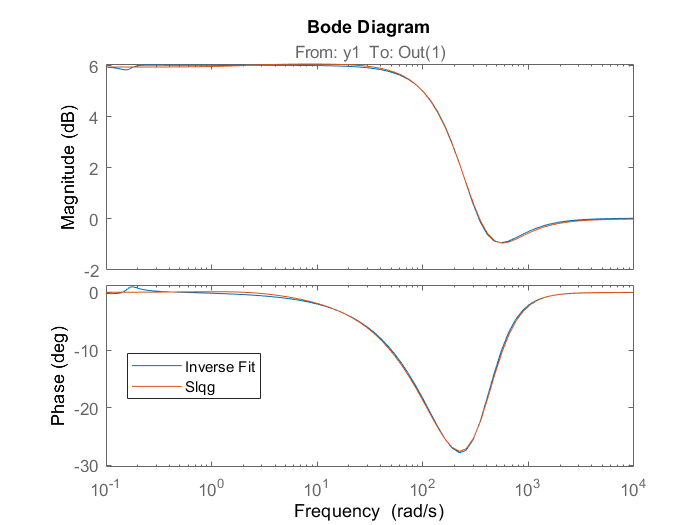


Wp = fitmagfrd(frd(1/Slqg,logspace(-5,4)),4);

% Inverse Fit
bode(1/Wp,Slqg)
legend("Inverse Fit","Slqg","Location","best")

# Q4(b)

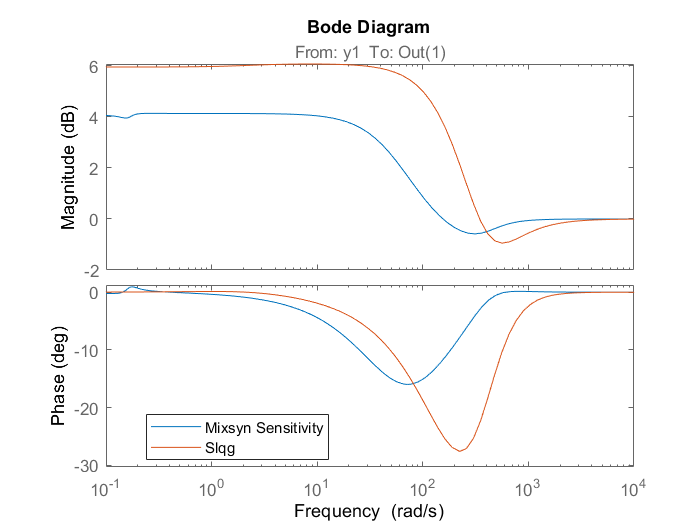

% Mixsyn
[K_mix,CL,gamma,info] = mixsyn(G,Wp,[],WI);
S_mix = 1-feedback(G_ss*K_mix,1);
bode(S_mix,Slqg)
legend("Mixsyn Sensitivity","Slqg","Location","best")


%Uncertain Sensitivity lqg
Gp = G*(1+WI*ultidyn('Delta',1));
S_unc_lqg = 1-feedback(Gp*Klqg,-1);
isstable(S_unc_lqg)

ans = logical
   1


[STABMARG,WCU] = robstab(S_unc_lqg);
mu_lqg = 1/STABMARG.LowerBound

mu_lqg = 1.3443

We can see that lqg controller is not robustly stable

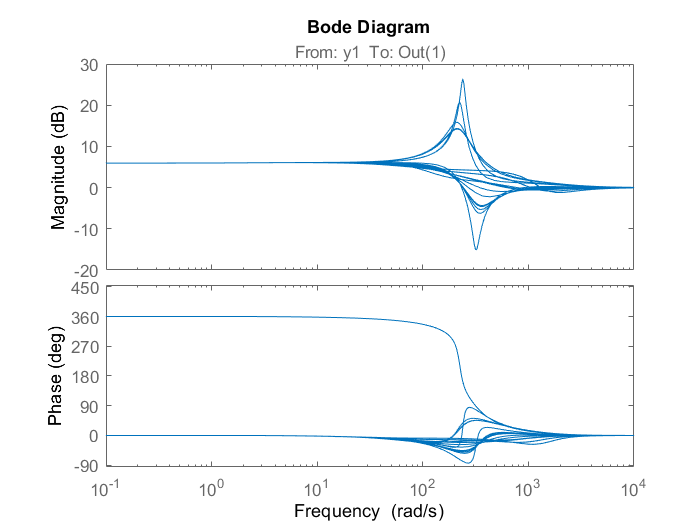

bode(S_unc_lqg)

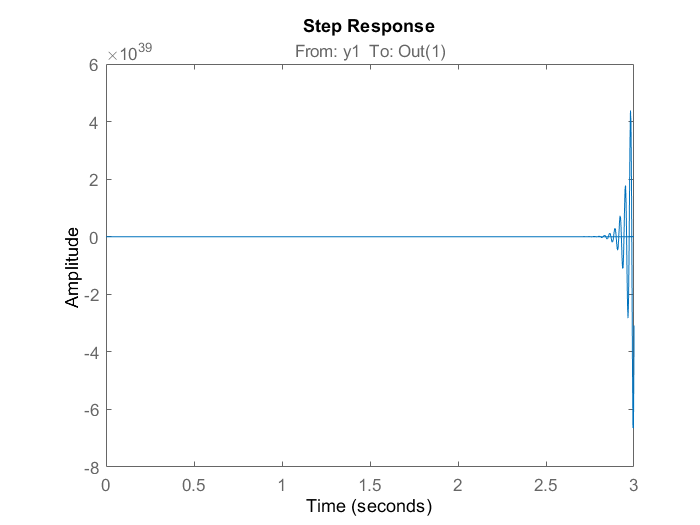

step(-(1-S_unc_lqg))

%Uncertain Sensitivity Mixsyn
S_unc = 1-feedback(Gp*K_mix,1);
isstable(S_unc)

ans = logical
   1


[STABMARG,WCU] = robstab(S_unc);
mu_mix = 1/STABMARG.LowerBound

mu_mix = 0.3152

We can see that mixsyn controller is robustly stable

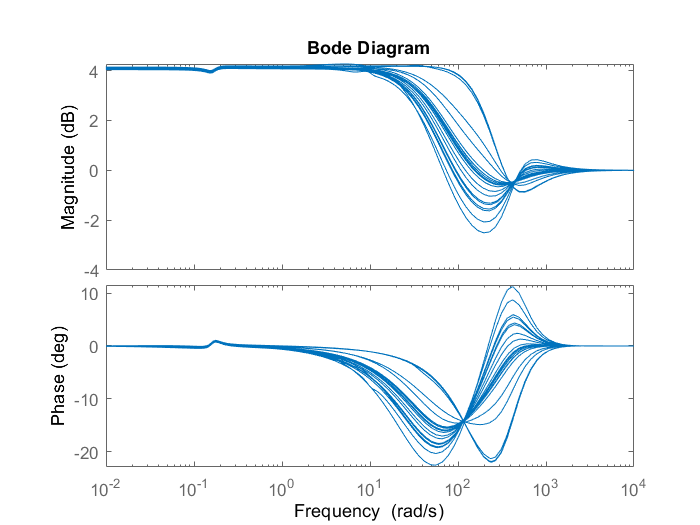

bode(S_unc)

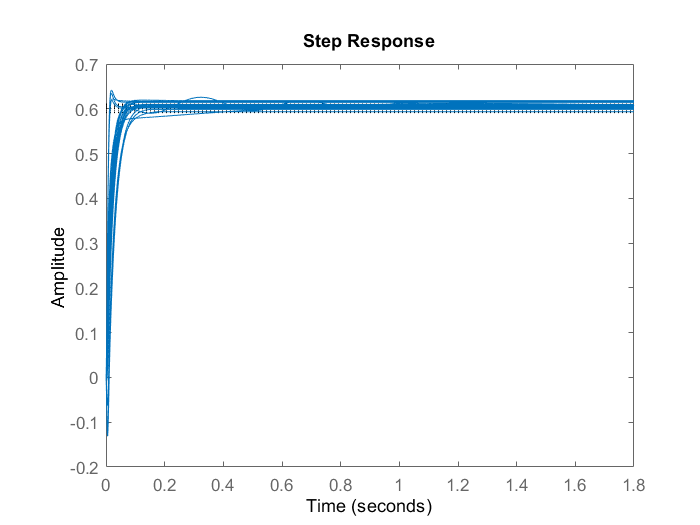

step(-(1-S_unc))